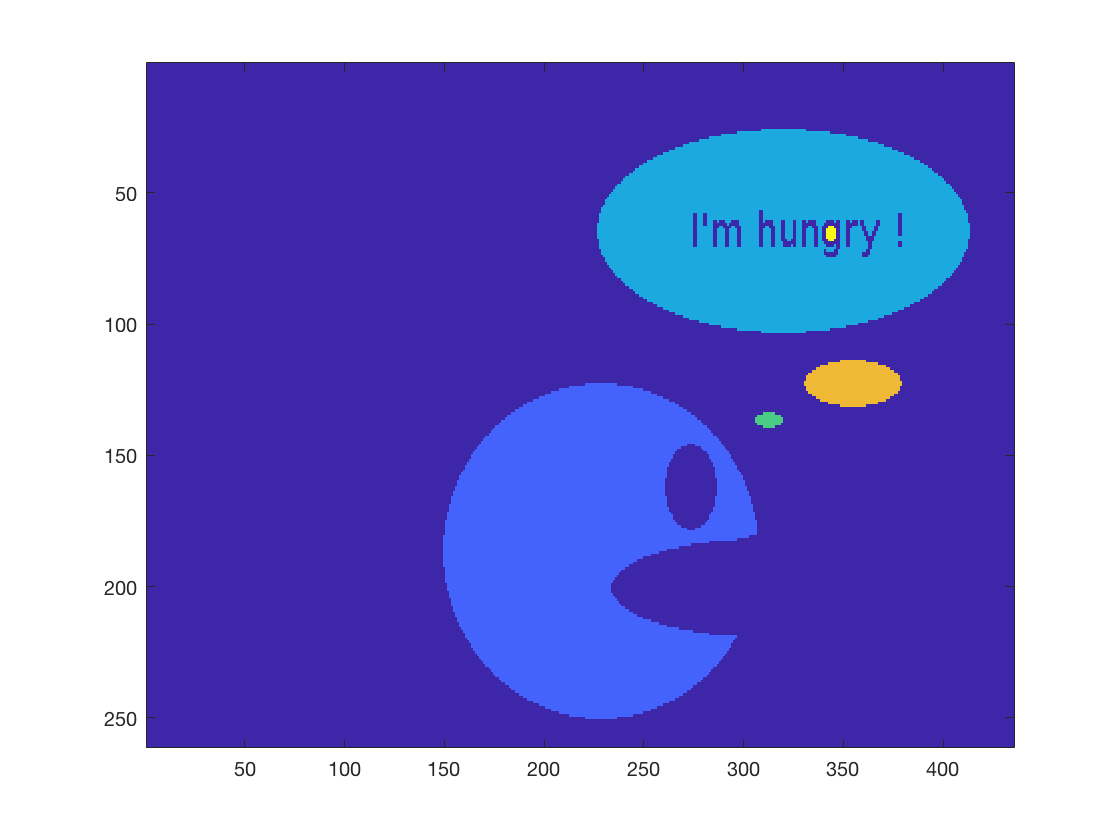

%ASSIGNMENT 4
%UTKARSH JAIN
%1
clear;
path='/Users/utkarsh/Desktop/';
img = double(imread(sprintf('%s/PACMAN_THINKS.jpg', path)));

img(img<=250) = 0;
img(img>250) = 1;

xmax = size(img,1);
ymax = size(img,2);

old_reg_locx = [];
old_reg_locy = [];

seg_loc = 0*img;

seg_label = 0;

[row,col] = find(img);

for i = 1:size(row)
    if(seg_loc(row(i),col(i))==0)
        old_reg_locx = [];
        old_reg_locy = [];
        reg_locx = row(i);
        reg_locy = col(i);
        seg_label = seg_label+1;
        while length(reg_locx)~=length(old_reg_locx)  
            old_reg_locx = reg_locx;
            old_reg_locy = reg_locy;
            reg_locx = [old_reg_locx; old_reg_locx; old_reg_locx; old_reg_locx+1;...
                old_reg_locx-1];
            reg_locy = [old_reg_locy; old_reg_locy-1; old_reg_locy+1; old_reg_locy;...
                old_reg_locy];
            bad = reg_locx<1 | reg_locx>xmax | reg_locy<1 | reg_locy>ymax;
            reg_locx = reg_locx(bad==0);
            reg_locy = reg_locy(bad==0);
            coord_all = [reg_locx, reg_locy];
            coord_all = unique(coord_all, 'rows');
            loc_linear = sub2ind(size(img), coord_all(:,1), coord_all(:,2));
            seg_loc(loc_linear) = seg_label*img(loc_linear);
            [reg_locx, reg_locy] = find(seg_loc == seg_label);
        end
    end
end

 figure
 imagesc(seg_loc)